# **Problem E12.16**

In this problem we are tasked with implementing the variations on the backpropagation algorithm for a $1-S^1 -1$ network in order to perform function approximation. To that end, we will a network with sigmoid activation on the hidden layer and a linear activation on the output layer.

Because we are asked to repeat the experiment several times, we have implemented every algorithm as a function  that takes $X$ and $Y$, the inputs and targets, $S^1$, the number of hidden neurons along the hyper paramaters of the algorithm. Each algorithm is fully explained in its separate file.

We will first generate a set of inputs and outputs for our problem which is approximating the function below:


$$g\left(p\right)=1+\sin \left(\frac{\pi }{2}p\right),\textrm{for}-2\le p\le 2$$


We will train a network with different algorithms for 100 epochs at a time. Then we will look at their MSEs on the test set to gauge:

- How well they have generalized.

- How well they have performed in the MSE sense.

In order to avoid overfitting $1-4-1$ structure for all of the models. The starting learning rate for all of the algorithms is set to $\eta ={10}^{-3}$.

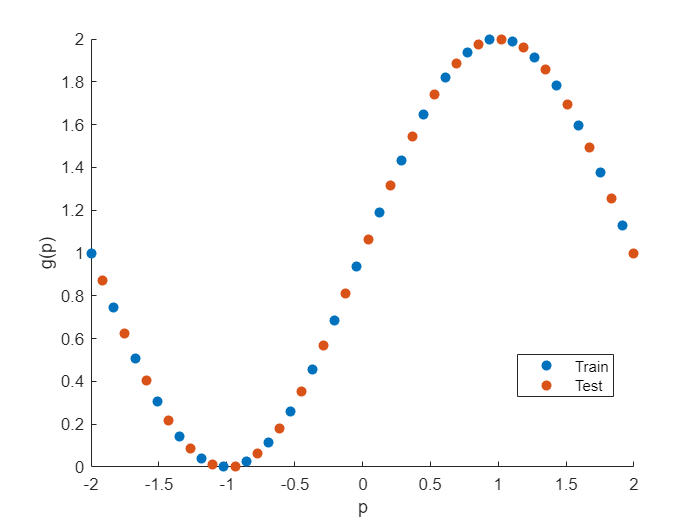

X = linspace(-2, 2, 50); % 20 linearly spaced vectors between -2 and 2
Y = 1 + sin(X.*pi/2);
% keep odd indices for training and even indices for testing
X_train = X(1:2:end);
Y_train = Y(1:2:end);
X_test = X(2:2:end);
Y_test = Y(2:2:end);
scatter(X, Y, 'filled');
hold on;
scatter(X_test, Y_test, 'filled');
legend('Train', 'Test', 'Location','best');
xlabel('p');
ylabel('g(p)');
hold off;

## Experiment 1: Batch Mode SDBP

[W1, W2, b1, b2, loss_hist] = batch_SDBP(X_train, Y_train, 4, 1e-3, 100);

Loss at the end of epoch 5: 0.683746
Loss at the end of epoch 10: 0.506324
Loss at the end of epoch 15: 0.449816
Loss at the end of epoch 20: 0.428957
Loss at the end of epoch 25: 0.418586
Loss at the end of epoch 30: 0.411281
Loss at the end of epoch 35: 0.404853
Loss at the end of epoch 40: 0.398660
Loss at the end of epoch 45: 0.392511
Loss at the end of epoch 50: 0.386352
Loss at the end of epoch 55: 0.380170
Loss at the end of epoch 60: 0.373965
Loss at the end of epoch 65: 0.367740
Loss at the end of epoch 70: 0.361502
Loss at the end of epoch 75: 0.355260
Loss at the end of epoch 80: 0.349022
Loss at the end of epoch 85: 0.342800
Loss at the end of epoch 90: 0.336604
Loss at the end of epoch 95: 0.330446
Loss at the end of epoch 100: 0.324337


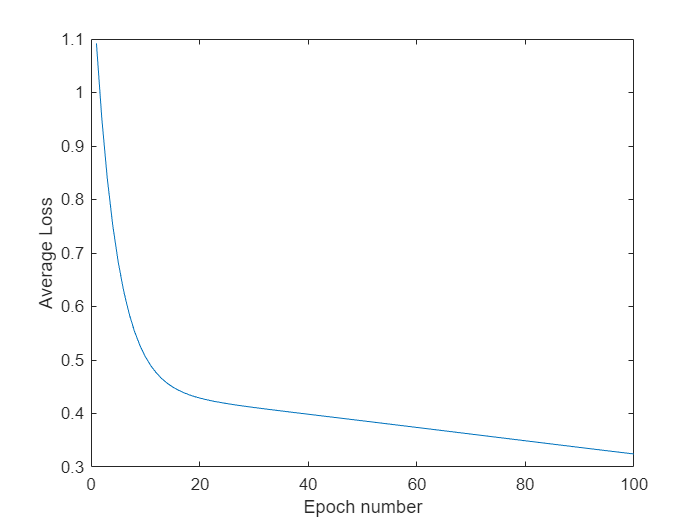

plot(loss_hist);
ylabel('Average Loss')
xlabel('Epoch number')

Y_pred = purelin(W2*logsig(W1*X_test + b1) + b2);
fprintf('MSE on the Test set: %f\n', mse(Y_test, Y_pred))

MSE on the Test set: 0.323480


As we can see batch mode SDBP provides a fairly stable learning curve and we do not see any oscillations as opposed to the stochastic steepest descent variant of backpropagation. If we were to use ${10}^{-2}$ as learning rate the algorithm would diverge. Using momentum we see below that convergence is possible with the same learning rate if we modify the momentum term.

## Experiment 2: MOBP

[W1, W2, b1, b2, loss_hist] = MOBP(X_train, Y_train, 4, 1e-2, 0.9998, 100);

Loss at the end of epoch 5: 1.666905
Loss at the end of epoch 10: 1.649988
Loss at the end of epoch 15: 1.621415
Loss at the end of epoch 20: 1.581838
Loss at the end of epoch 25: 1.532151
Loss at the end of epoch 30: 1.473472
Loss at the end of epoch 35: 1.407111
Loss at the end of epoch 40: 1.334539
Loss at the end of epoch 45: 1.257354
Loss at the end of epoch 50: 1.177243
Loss at the end of epoch 55: 1.095937
Loss at the end of epoch 60: 1.015181
Loss at the end of epoch 65: 0.936683
Loss at the end of epoch 70: 0.862084
Loss at the end of epoch 75: 0.792918
Loss at the end of epoch 80: 0.730583
Loss at the end of epoch 85: 0.676306
Loss at the end of epoch 90: 0.631123
Loss at the end of epoch 95: 0.595859
Loss at the end of epoch 100: 0.571109


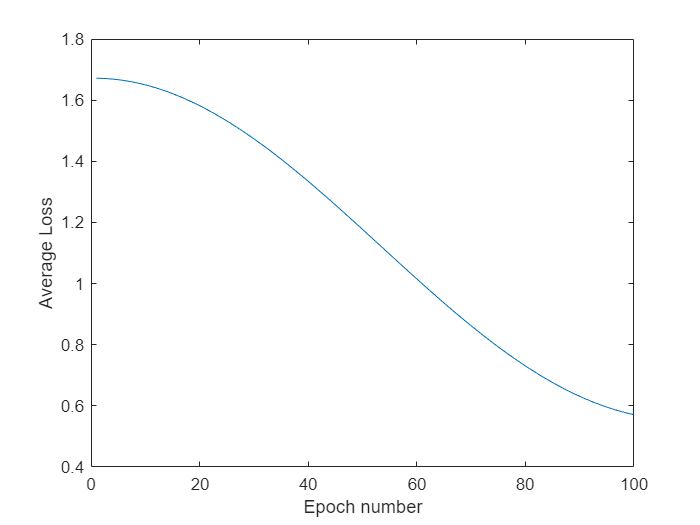

plot(loss_hist);
ylabel('Average Loss')
xlabel('Epoch number')

Y_pred = purelin(W2*logsig(W1*X_test + b1) + b2);
fprintf('MSE on the Test set: %f\n', mse(Y_test, Y_pred))

MSE on the Test set: 0.567334


As we can see the learning is unstable but we still converge eventually.

However, if we want to get better results, it's best to set the learning rate to a smaller value.

[W1, W2, b1, b2, loss_hist] = MOBP(X_train, Y_train, 4, 1e-3, 0.9, 100);

Loss at the end of epoch 5: 4.886016
Loss at the end of epoch 10: 2.741867
Loss at the end of epoch 15: 1.120070
Loss at the end of epoch 20: 0.382880
Loss at the end of epoch 25: 0.217821
Loss at the end of epoch 30: 0.260136
Loss at the end of epoch 35: 0.309332
Loss at the end of epoch 40: 0.311070
Loss at the end of epoch 45: 0.280648
Loss at the end of epoch 50: 0.245516
Loss at the end of epoch 55: 0.221151
Loss at the end of epoch 60: 0.209569
Loss at the end of epoch 65: 0.206153
Loss at the end of epoch 70: 0.205811
Loss at the end of epoch 75: 0.205621
Loss at the end of epoch 80: 0.204765
Loss at the end of epoch 85: 0.203483
Loss at the end of epoch 90: 0.202198
Loss at the end of epoch 95: 0.201136
Loss at the end of epoch 100: 0.200314


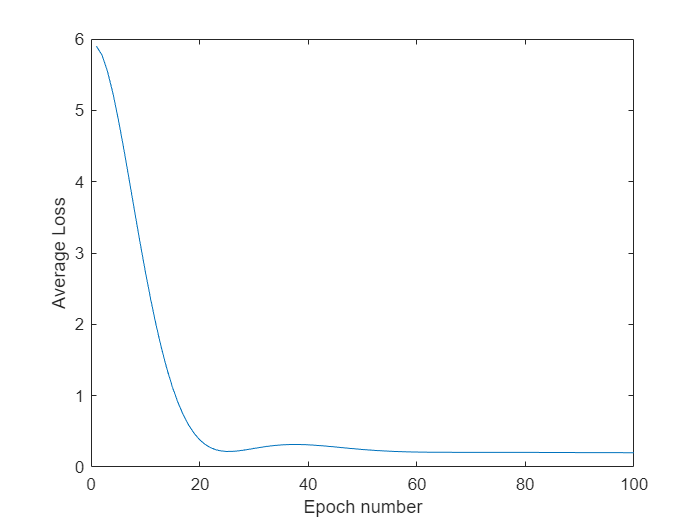

plot(loss_hist);
ylabel('Average Loss')
xlabel('Epoch number')

Y_pred = purelin(W2*logsig(W1*X_test + b1) + b2);
fprintf('MSE on the Test set: %f\n', mse(Y_test, Y_pred))

MSE on the Test set: 0.195552


This gives us a much faster learning and a significantly better final MSE on the test set.

## Experiment 3: VLBP

[W1, W2, b1, b2, loss_hist, lr_hist] = VLBP(X_train, Y_train, 4, 1e-3, 0.9, 0.04, 0.7, 1.05, 100);

Loss at the end of epoch 5: 6.817223
Loss at the end of epoch 10: 3.303340
Loss at the end of epoch 15: 0.994680
Loss at the end of epoch 20: 0.668706
Loss at the end of epoch 25: 0.568275
Loss at the end of epoch 30: 0.513380
Loss at the end of epoch 35: 0.466260
Loss at the end of epoch 40: 0.395284
Loss at the end of epoch 45: 0.330129
Loss at the end of epoch 50: 0.273124
Loss at the end of epoch 55: 0.217767
Loss at the end of epoch 60: 0.176402
Loss at the end of epoch 65: 0.148387
Loss at the end of epoch 70: 0.135772
Loss at the end of epoch 75: 0.132648
Loss at the end of epoch 80: 0.130875
Loss at the end of epoch 85: 0.126004
Loss at the end of epoch 90: 0.119694
Loss at the end of epoch 95: 0.113669
Loss at the end of epoch 100: 0.106180


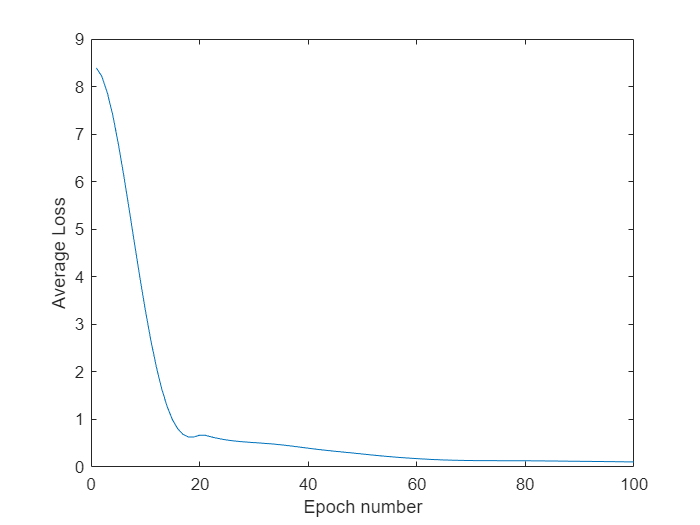

plot(loss_hist);
ylabel('Average Loss')
xlabel('Epoch number')

Y_pred = purelin(W2*logsig(W1*X_test + b1) + b2);
fprintf('MSE on the Test set: %f\n', mse(Y_test, Y_pred))

MSE on the Test set: 0.105810


We can see a faster convergence and a better final result on the test MSE using VLBP compared to MOBP.

We can also plot the learning rate history to see how the learning rate changes across different epochs:

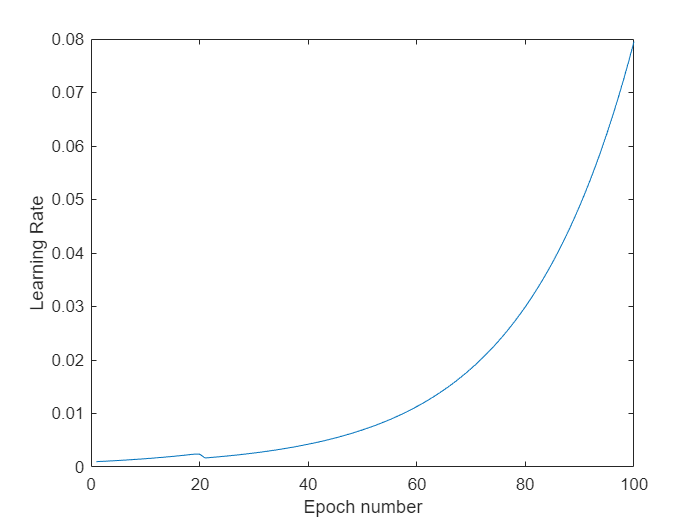

plot(lr_hist);
ylabel('Learning Rate')
xlabel('Epoch number')

Because we start with a small initial learning rate, the learning rate sees an steady increase as epochs progress.

## Experiment 4: CGBP

NOTE: Because we are training on a single-featured space, we have to reset the search direction to gradient descent at every step for this problem specifically. However the CGBP implementation below should work with any feature space.

[W1, W2, b1, b2, loss_hist] = CGBP(X_train, Y_train, 4, 2e-4, 1e-6, 100);

Loss at the end of epoch 5: 0.430649
Loss at the end of epoch 10: 0.173613
Loss at the end of epoch 15: 0.161044
Loss at the end of epoch 20: 0.145052
Loss at the end of epoch 25: 0.129901
Loss at the end of epoch 30: 0.115099
Loss at the end of epoch 35: 0.105059
Loss at the end of epoch 40: 0.101339
Loss at the end of epoch 45: 0.096646
Loss at the end of epoch 50: 0.093292
Loss at the end of epoch 55: 0.079738
Loss at the end of epoch 60: 0.076627
Loss at the end of epoch 65: 0.064538
Loss at the end of epoch 70: 0.062202
Loss at the end of epoch 75: 0.059204
Loss at the end of epoch 80: 0.049329
Loss at the end of epoch 85: 0.047266
Loss at the end of epoch 90: 0.045891
Loss at the end of epoch 95: 0.043070
Loss at the end of epoch 100: 0.038591


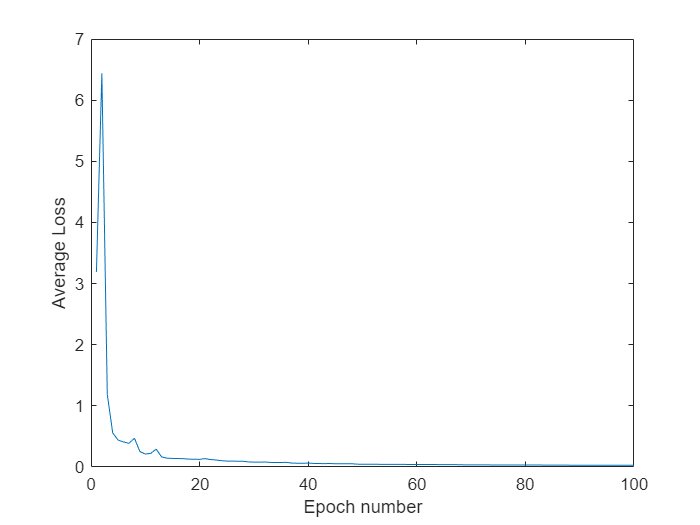

plot(loss_hist);
ylabel('Average Loss')
xlabel('Epoch number')

Y_pred = purelin(W2*logsig(W1*X_test + b1) + b2);
fprintf('MSE on the Test set: %f\n', mse(Y_test, Y_pred))

MSE on the Test set: 0.039144


As we can observe the learning is slightly unstable at the beginning but it converges very quickly and the end result is even better than VLBP as we get a smaller MSE on the Test set.

## Experiment 5: LMBP

[W1, W2, b1, b2, loss_hist] = LMBP(X_train, Y_train, 4, 1e-3, 3, 100);

Loss at the end of epoch 5: 0.064631
Loss at the end of epoch 10: 0.005376
Loss at the end of epoch 15: 0.000003
Loss at the end of epoch 20: 0.000003
Loss at the end of epoch 25: 0.000002
Loss at the end of epoch 30: 0.000004
Loss at the end of epoch 35: 0.000002
Loss at the end of epoch 40: 0.000002
Loss at the end of epoch 45: 0.000002
Loss at the end of epoch 50: 0.000002
Loss at the end of epoch 55: 0.000002
Loss at the end of epoch 60: 0.000001
Loss at the end of epoch 65: 0.000001
Loss at the end of epoch 70: 0.000001
Loss at the end of epoch 75: 0.000001
Loss at the end of epoch 80: 0.000002
Loss at the end of epoch 85: 0.000001
Loss at the end of epoch 90: 0.000003
Loss at the end of epoch 95: 0.000023
Loss at the end of epoch 100: 0.000000


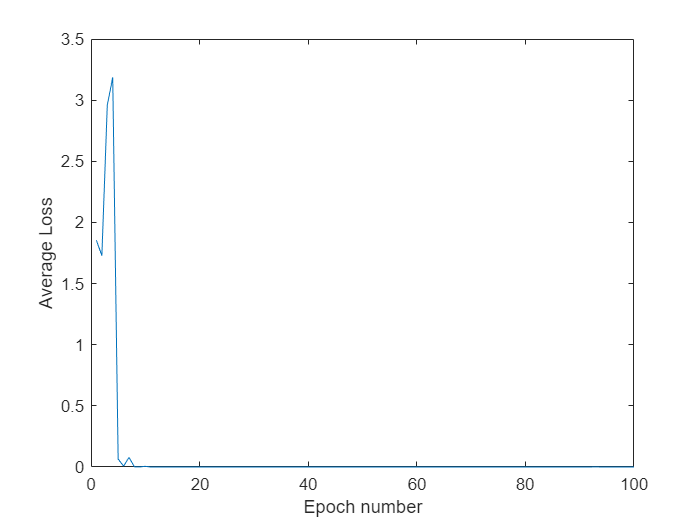

plot(loss_hist);
ylabel('Average Loss')
xlabel('Epoch number')

Y_pred = purelin(W2*logsig(W1*X_test + b1) + b2);
fprintf('MSE on the Test set: %f\n', mse(Y_test, Y_pred))

MSE on the Test set: 0.000001


As we can see, due to the relaxation steps taken, it is possible for the loss to incresase in two consequent epochs. However, once the algorithm finds it footing, it converges to the minimum lightning fast. From the example above we see than it took about 15 epochs for the algorithm to converge to a solution. Moreover, it is also the most accurate version of backpropagation so far with a mere 0.000001 MSE on the test set which is leaps and bounds better than everything else we have seen so far.